Assignment 3, ENGS 27 Summer 2023 Solutions

**Problem 1A.**

to find the total number of words possible, we just need to do 3^31 for all of the combinations. The format was also changed to long because a lot of these numbers are extremely similar.

format long
P1A = 3^31

P1A =      6.176733962839470e+14


Problem 1B.

**Problem 1C.**

We just need to construct the transition matrices, and then find the number of words length 31 in L, and divide that by the total possible words 3^31.

% construct matrices
Ma=[0 1 0 0;
    0 0 0 0;
    0 0 0 0;
    1 0 0 0];

Mb=[1 0 0 0;
    0 0 1 0;
    0 0 0 0;
    0 0 0 0];

Mc=[0 0 0 1;
    0 0 0 0;
    1 0 0 0;
    0 0 0 0];

% formula for finding # of words of a length
startNodeP1 = [1 0 0 0];
acceptingNodesP1 = [1 0 0 0]';
numwords = startNodeP1*(Ma+Mb+Mc)^31*acceptingNodesP1;

P1C = numwords/3^31

P1C =      1.601980862302061e-07


**Problem 2.**

Part A— For this problem, we again need to make a transition matrix, and then repeat the same process as for 1C, but adding up all of the paths from 1:20 instead of just 20.

Part B— we use a similar approach, but instead we find the total number of paths that do NOT include i = 3,4,5, and subtract that from the total number of paths to get the number of paths that do have these nodes. after we divide by the total paths to get it as a probability.


% normal matrix
matrix_n  = [0 1 0 0 0;
             1 1 1 0 0;
             1 1 1 1 0;
             1 0 0 1 1;
             1 0 0 1 0];

% matrix excluding 3
matrix_3 =  [0 1 0 0 0;
             1 1 0 0 0;
             1 1 0 1 0;
             1 0 0 1 1;
             1 0 0 1 0];

% matrix excluding 4
matrix_4 =  [0 1 0 0 0;
             1 1 1 0 0;
             1 1 1 0 0;
             1 0 0 0 1;
             1 0 0 0 0];

% matrix excluding 5
matrix_5 =  [0 1 0 0 0;
             1 1 1 0 0;
             1 1 1 1 0;
             1 0 0 1 0;
             1 0 0 1 0];

startNodeP2 =       [0 1 0 0 0];
acceptingNodesP2 =  [1 0 0 0 0]';
paths = zeros(20,1);

% switches which matrix is used
for i = [1 3 4 5]
    switch i
        case 3
            matrix = matrix_3;
        case 4
            matrix = matrix_4;
        case 5
            matrix = matrix_5;
        otherwise
            matrix = matrix_n;
    end
    % tests all lengths from 1:20
    for k=1:20
        paths(k)= startNodeP2*matrix^k*acceptingNodesP2;
    end
    pathlist(i,:) = paths;
end
P2A = sum(pathlist(1,:))

P2A =     97556236


P2B_3 = (sum(pathlist(1,:)) - sum(pathlist(3,:)))/sum(pathlist(1,:))

P2B_3 =    0.999818463680784


P2B_4 = (sum(pathlist(1,:)) - sum(pathlist(4,:)))/sum(pathlist(1,:))

P2B_4 =    0.720118394071702


P2B_5 = (sum(pathlist(1,:)) - sum(pathlist(5,:)))/sum(pathlist(1,:))

P2B_5 =    0.379018764110579


for problem b we do a similar approach but we zero out the column we are looking for

Problem 2C:

If a path of length k is reciporical to the probability of choosing that path, the probability of choosing that path is c/k, where c is a constant to normalize the sum to 1 to ensure it becomes a probability. to do this we take the number of paths for each value of k and divide that by the length of those paths, and then do one over the sum all of the answers we got from this to find C. 

% dividing each row by its length
P2C = (pathlist(1,:)./[1:20])';

% now we find the constant 
C = 1/sum(P2C);
P2C = C * P2C

P2C =    0.000000197835448
   0.000000197835448
   0.000000395670896
   0.000000791341792
   0.000001661817763
   0.000003594010639
   0.000007941680127
   0.000017879378612
   0.000040842029152
   0.000094426859327


sum(P2C) % check it adds up to 1

ans =    1.000000000000000


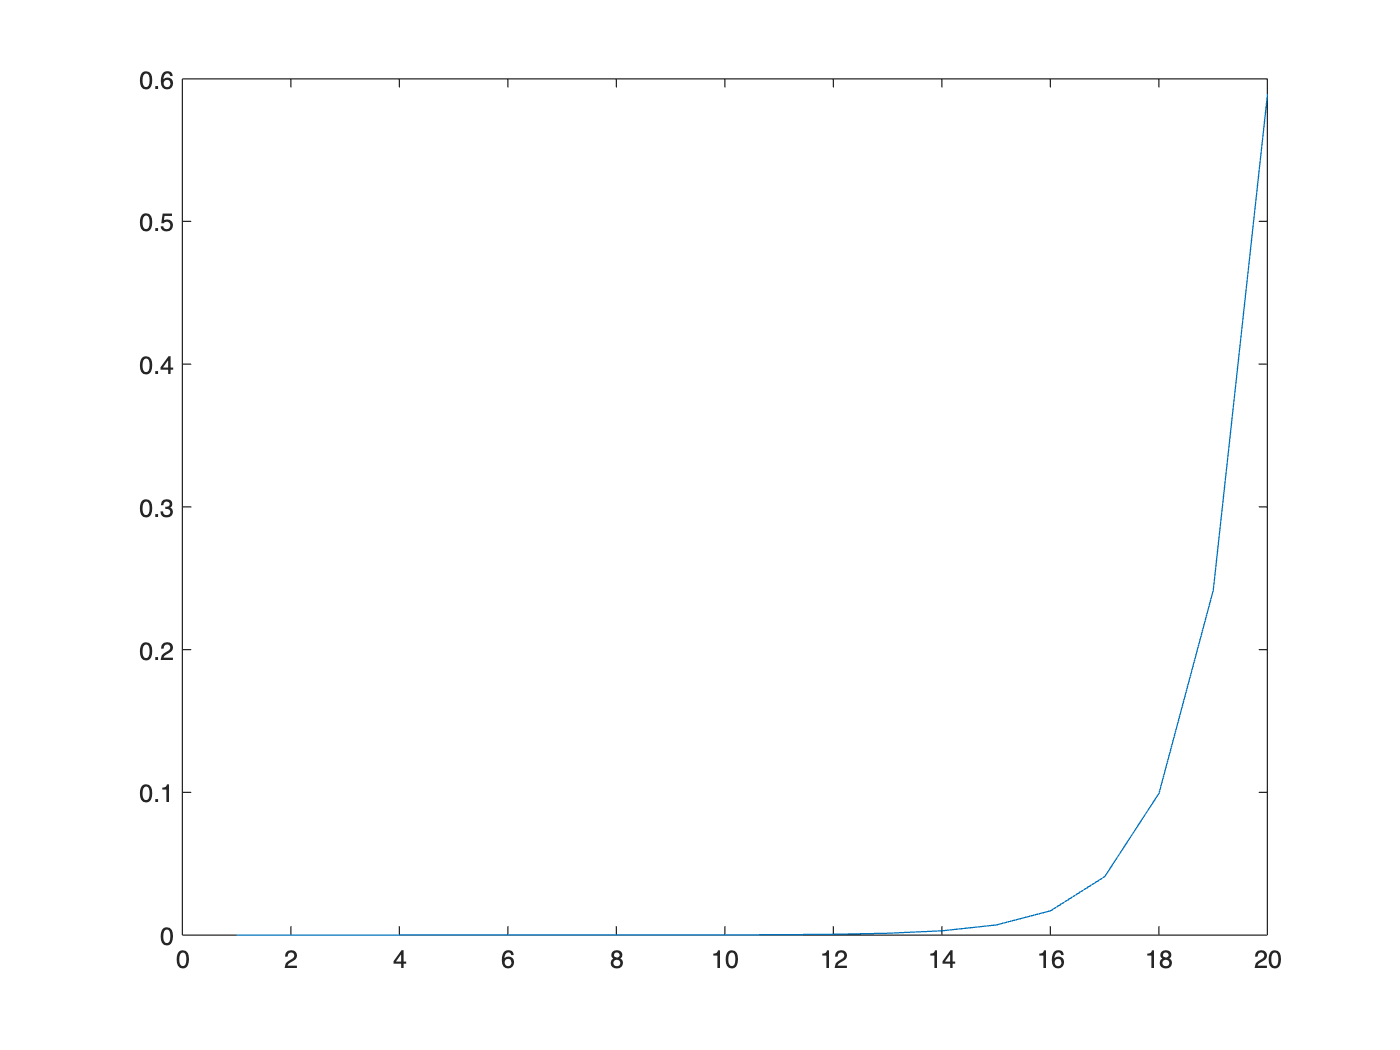

figure
plot(P2C)  % take a look at the probabilities

**Problem 2D.**

For this, we combine our approach to 2B and 2C. we find the number of paths that include 3, divide by length, and then normalize with C.

% get paths with 3
pathlistwith3 = (pathlist(1,:)-pathlist(3,:))' ;
% divide and normalize
probpathlistwith3 = C*pathlistwith3./[1:20]';
% sum
P2D_3 = sum(probpathlistwith3)

P2D_3 =    0.999805704617861


% repeat for 4
pathlistwith4 = (pathlist(1,:)-pathlist(4,:))' ;
probpathlistwith4 = C*pathlistwith4./[1:20]';
P2D_4 = sum(probpathlistwith4)

P2D_4 =    0.718949486568486


% repeat for 5
pathlistwith5 = (pathlist(1,:)-pathlist(5,:))' ;
probpathlistwith5 = C*pathlistwith5./[1:20]';
P2D_5 = sum(probpathlistwith5)

P2D_5 =    0.378026666702715


Problem 2e.

for i = 3:  the probability is 100%.

for i = 4:

First we make a gate that when multiplied by the regular transition matrix will add node 3 back in. the way that this problem works is first, the matrix is raised to power j but it doesnt have node 3 or 4, after j steps we take another step with node 3 added (this happens through matrix_n*Gate3), and then we do the rest of the steps up to 20 without node 4. essentially what this does it allows node 4 to only be visited after node 3 has been visited, and allows revisits to nod 3 after it is initially visited. after we get out number, we do 1 - the probability we get to find the nodes that DO go through node 4 given the path passes through node 3.

% make the gate that adds node 3 back in after j steps
Gate3=zeros(5,5); Gate3(3,3)=1;


%matrix without 3 or 4
matrix_34 = matrix_3;
matrix_34(:,4)=zeros(5,1);

totpathsthrough3not4=zeros(20,1);

for k=1:20
    for j=0:k-1
        totpathsthrough3not4(k) = totpathsthrough3not4(k)+[ 0 1 0 0 0]*(matrix_34)^j*matrix_n*Gate3*matrix_4^(k-j-1)*[1;0;0;0;0];
    end
end

Now put it all together..

% normalize total paths
Probthrough3=sum(C*pathlistwith3./[1:20]');

% normalize through 3 but not 4
Probthrough3not4=sum(C*totpathsthrough3not4./[1:20]');

%get the complemet of this probability for 2E_4
P2E_4 = 1 - Probthrough3not4/Probthrough3

P2E_4 =    0.719089202279835


Repeat for 5

% make the gate that adds node 3 back in after j steps
Gate3=zeros(5,5); Gate3(3,3)=1;

%matrix without 3 or 5
matrix_35 = matrix_3;
matrix_35(:,5) = zeros(5,1);


totpathsthrough3not5=zeros(20,1);
for k=1:20
    for j=0:k-1
        totpathsthrough3not5(k) = totpathsthrough3not5(k)+[ 0 1 0 0 0]*(matrix_35)^j*matrix_n*Gate3*matrix_5^(k-j-1)*[1;0;0;0;0];
    end
end

% normalize total paths
Probthrough3 =sum(C*pathlistwith3./[1:20]');
% normalize through 3 but not 5
Probthrough3not5 = sum(C*totpathsthrough3not5./[1:20]');
%get the complemet of this probability for 2E_5
Answer2e_5 = 1 - Probthrough3not5/Probthrough3

Answer2e_5 =    0.378100129811924


**Problem 3.**

For this problem we just repeat problem 1 and 5, assignment 1.

load("celegans_metabolic.net");
maxnum = max(celegans_metabolic(:,1));
g = graph(celegans_metabolic(:,1),celegans_metabolic(:,2));
mat = full(adjacency(g));

numfriends = zeros(maxnum,2); %initialize matrices first
numfriends(:,1) = 1:maxnum;
numfriends(:,2) = sum(mat);

pathlength = zeros(maxnum);
%initializing

P3A = sortrows(numfriends,2,'descend')

P3A =    186   238
   147   124
   408   109
   145   105
   227    75
   228    75
   153    64
   205    64
   426    63
   231    61


for i = 1:maxnum

    for j = 1:maxnum

        if (i ~= j) %we want to exclude going through itself

            [path, pathlength(i,j)] = shortestpath(g,i,j);
            %just shortest path function
        end
    end

end

M = max(pathlength(:));
[node1,node2] = find(pathlength == M);
table(node1,node2)

ans = 48×2 table
    node1    node2
    _____    _____

     138        8 
     225        8 
     138       15 
     225       15 
     138       19 
     225       19 
     138       20 
     225       20 
     138       21 
     225       21 
     138       22 
     225       22 
     138       23 
     225       23 
       8      138 
      15      138 


**Problem 4.**

For this problem we use Bayes' rule to find the probability of getting urn 1 given that we have drawn 7 red abd 1 blue marble.

A = 0.5;
B = (30/37)^7*7/37;
Ac = (1/2)^8;

(A*B)/((B*A)+(Ac*A))

ans =    0.917747307509136
